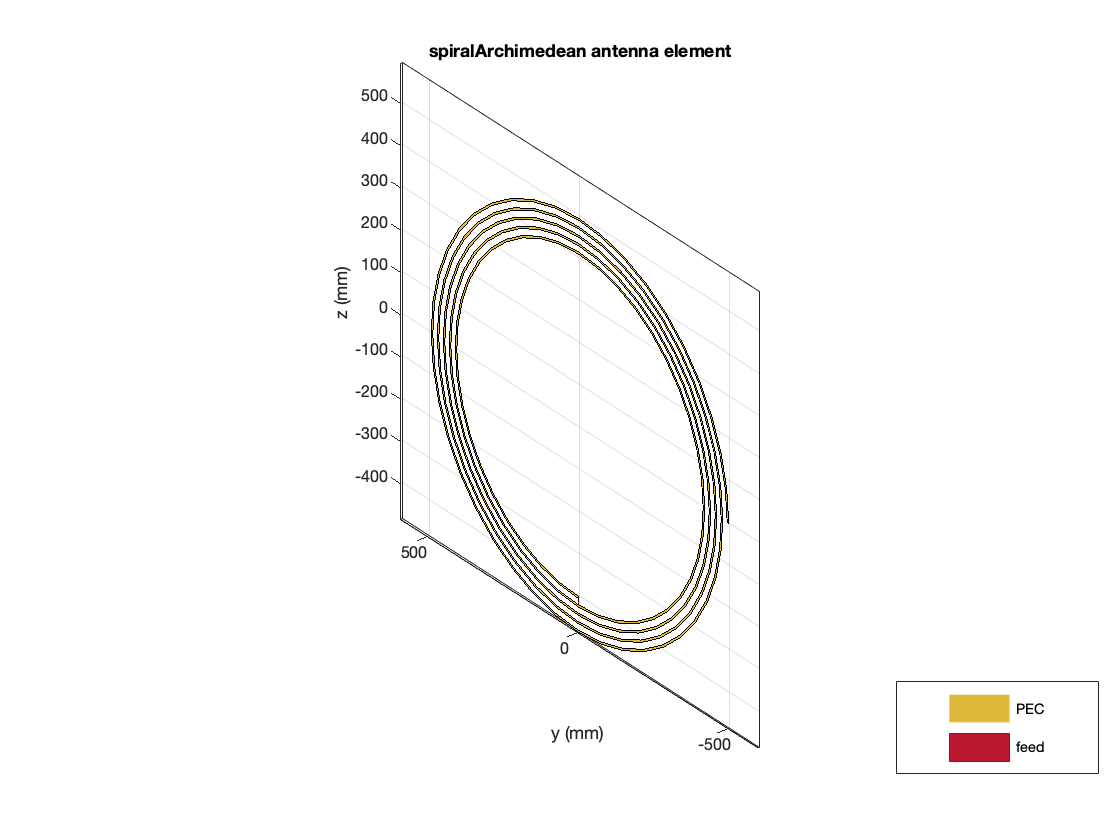

% 1
arms = 1;
voltas = 5;
raio_interno = 0.4;
raio_externo = 0.5;

antena = spiralArchimedean('NumArms', arms, 'Turns', voltas, 'InnerRadius', raio_interno, 'OuterRadius', raio_externo, 'Tilt', 90, 'TiltAxis', 'Y');
show(antena)

% 2
frequencia = linspace(4000000,10000000,200);
z = impedance(antena,frequencia);
imaginario_z = imag(z)

imaginario_z = 	1.0e+04 *

    0.0094    0.0096    0.0097    0.0098    0.0099    0.0100    0.0102    0.0103    0.0104    0.0105    0.0107    0.0108    0.0110    0.0111    0.0112    0.0114    0.0115    0.0117    0.0118    0.0120    0.0122    0.0123    0.0125    0.0127    0.0129    0.0131    0.0132    0.0134    0.0136    0.0138    0.0141    0.0143    0.0145    0.0147    0.0150    0.0152    0.0155    0.0157    0.0160    0.0163    0.0166    0.0169    0.0172    0.0176    0.0179    0.0183    0.0187    0.0191    0.0195    0.0200


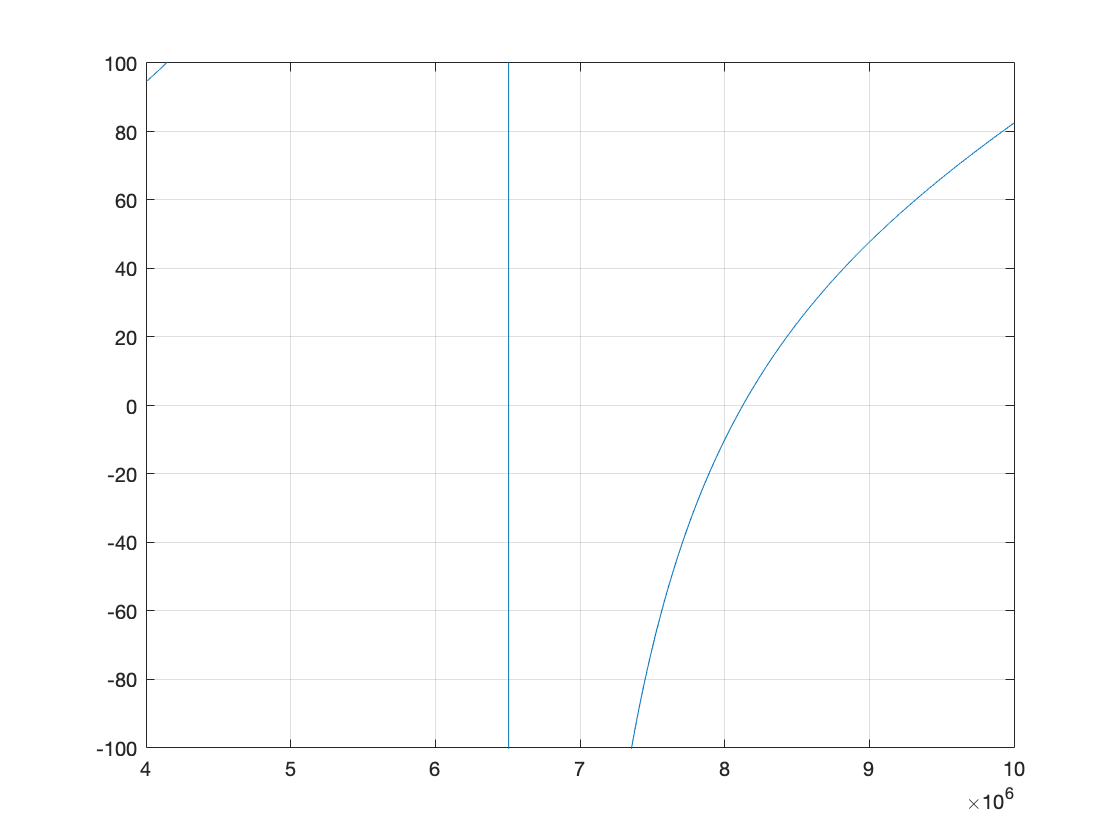


plot(frequencia, imaginario_z)
ylim([-100 100])
grid on

% 3
antena_receptora = spiralArchimedean('NumArms', arms, 'Turns', voltas, 'InnerRadius', raio_interno, 'OuterRadius', raio_externo, 'Tilt', 90, 'TiltAxis', 'Y');
show(antena)

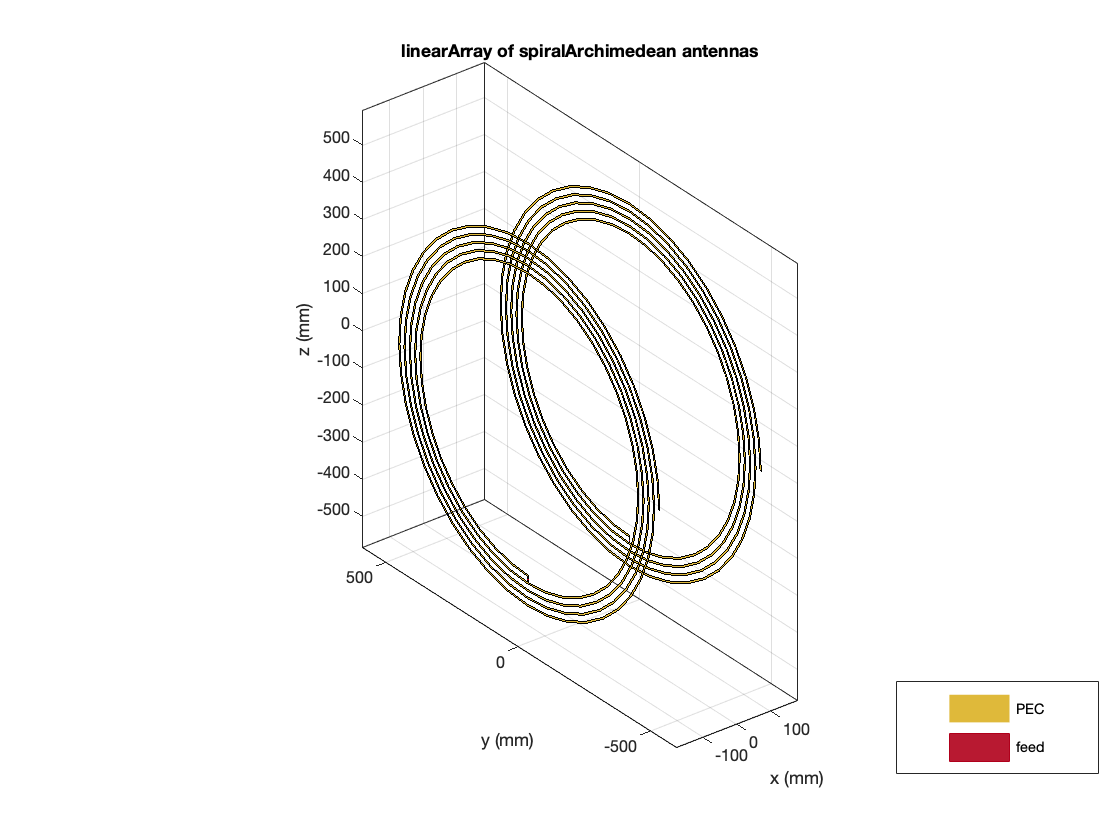

% 4
array = linearArray('Element',[antena, antena_receptora]);
array.ElementSpacing = 0.30;
show(array)

% 5
ganho = sparameters(array,frequencia)

ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


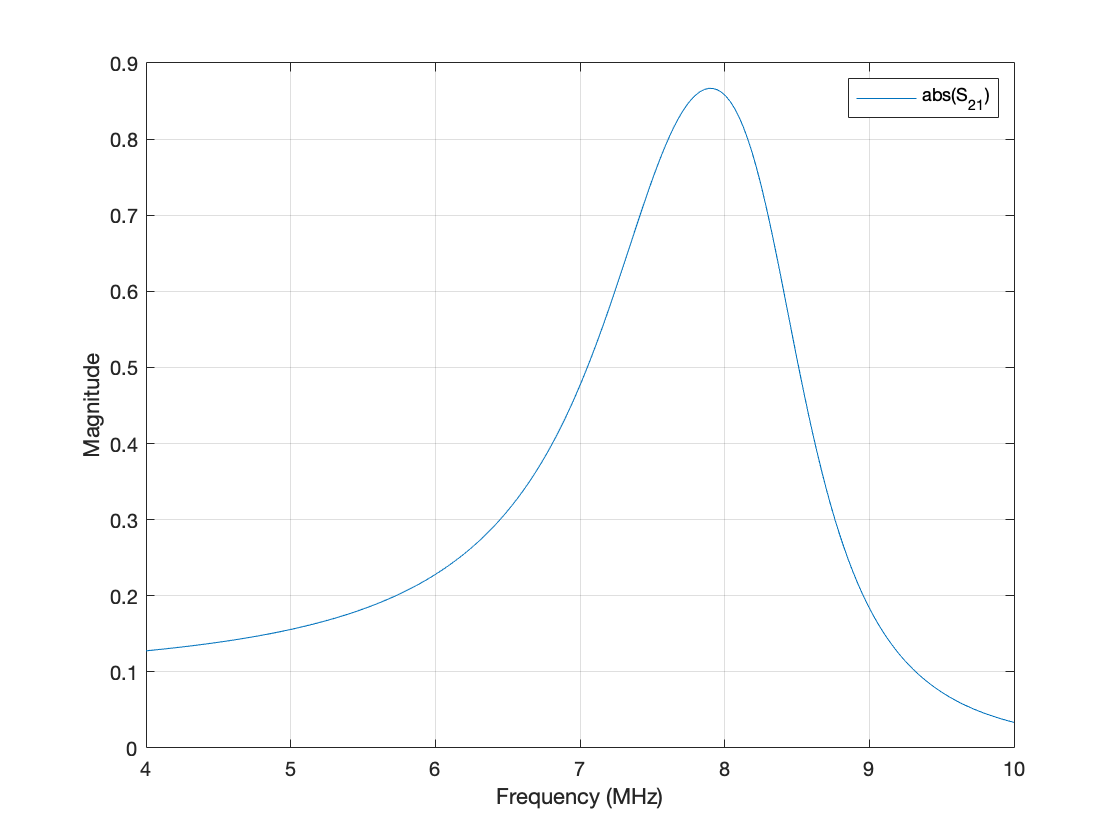

rfplot(ganho,2,1,'abs')

% 6
col = 1

col = 1

for d = 0.10:0.08:1
    array = linearArray('Element',[antena, antena_receptora]);
    array.ElementSpacing = d;
    ganho1 = sparameters(array,frequencia);
    ganho_z = rfparam(ganho1,2,1);
    ganho_a(col,:) = ganho_z
    col = col + 1
end

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i


col = 2

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 3

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 4

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 5

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 6

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 7

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 8

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 9

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 10

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 11

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 12

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 13

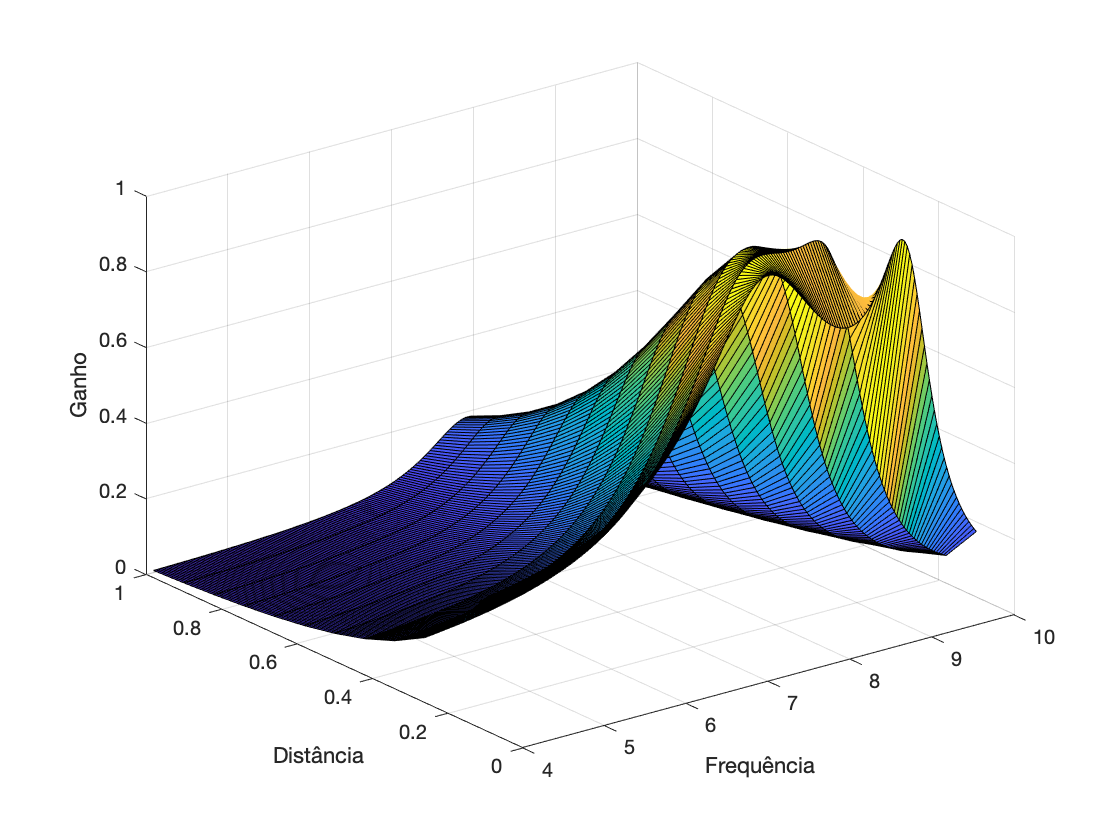



[X,Y] = meshgrid(frequencia/1e6,[0.10:0.08:1]);
surf(X,Y,abs(ganho_a))
xlabel("Frequência")
ylabel("Distância")
zlabel("Ganho")

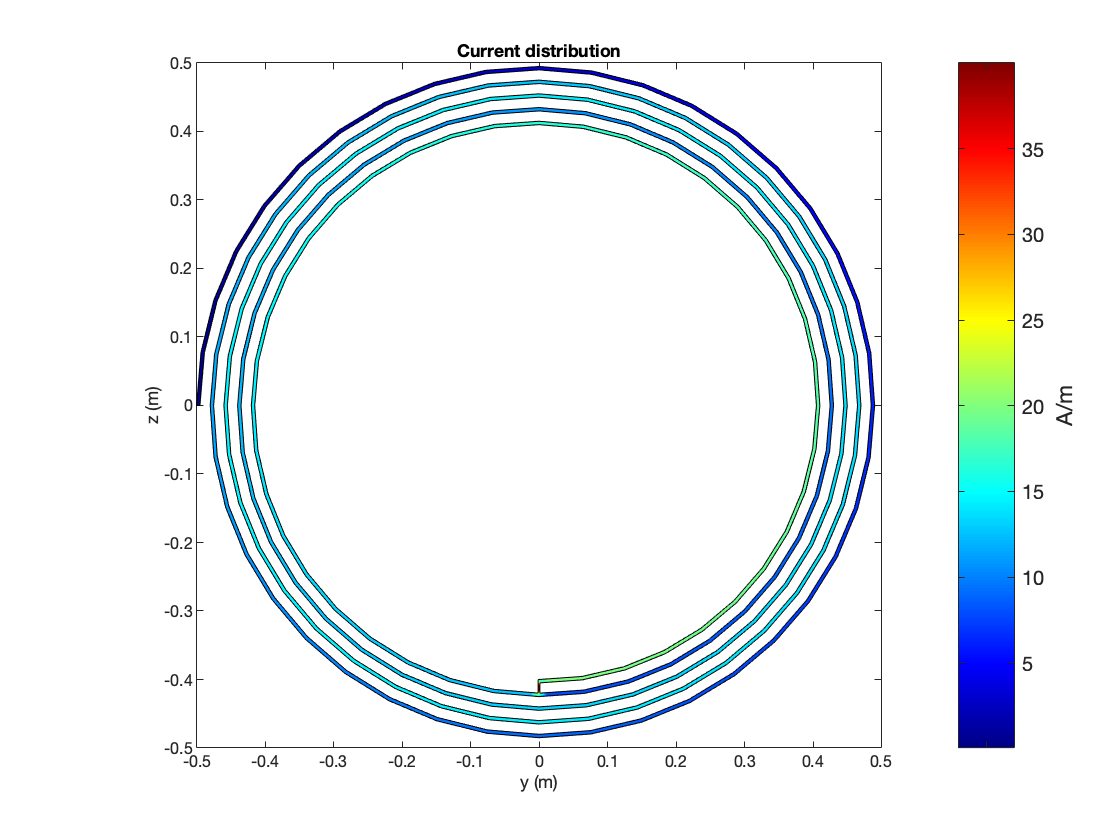

% 7- item opicional
% média de freq de ressonância = 8*1e6
current(antena,8*1e6)

%extra (distancia por ganho)
freq_g = frequencia(133)

freq_g = 7.9799e+06

dist = [0.10:0.08:1]

dist =     0.1000    0.1800    0.2600    0.3400    0.4200    0.5000    0.5800    0.6600    0.7400    0.8200    0.9000    0.9800



col = 1

col = 1

for d = 0.10:0.08:1
    array = linearArray('Element',[antena, antena_receptora]);
    array.ElementSpacing = d;
    ganho = sparameters(array,frequencia);
    ganho_z = rfparam(ganho,2,1);
    ganho_a(col,:) = ganho_z
    col = col + 1
end

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i


col = 2

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 3

ganho_a =    0.2993 - 0.1833i   0.2985 - 0.1868i   0.2976 - 0.1903i   0.2967 - 0.1938i   0.2958 - 0.1973i   0.2948 - 0.2008i   0.2939 - 0.2043i   0.2929 - 0.2078i   0.2920 - 0.2113i   0.2910 - 0.2149i   0.2900 - 0.2184i   0.2890 - 0.2220i   0.2879 - 0.2256i   0.2869 - 0.2292i   0.2858 - 0.2328i   0.2847 - 0.2365i   0.2837 - 0.2401i   0.2826 - 0.2438i   0.2814 - 0.2475i   0.2803 - 0.2513i   0.2791 - 0.2551i   0.2780 - 0.2589i   0.2768 - 0.2627i   0.2756 - 0.2666i   0.2743 - 0.2705i   0.2731 - 0.2744i   0.2718 - 0.2784i   0.2705 - 0.2825i   0.2692 - 0.2865i   0.2679 - 0.2907i   0.2665 - 0.2949i   0.2651 - 0.2991i   0.2637 - 0.3034i   0.2622 - 0.3077i   0.2607 - 0.3122i   0.2592 - 0.3166i   0.2577 - 0.3212i   0.2561 - 0.3258i   0.2544 - 0.3305i   0.2527 - 0.3353i   0.2510 - 0.3401i   0.2493 - 0.3450i   0.2474 - 0.3501i   0.2455 - 0.3552i   0.2436 - 0.3604i   0.2416 - 0.3657i   0.2395 - 0.3711i   0.2374 - 0.3766i   0.2352 - 0.3822i   0.2329 - 0.3879i
   0.2013 - 0.1317i   0.2007 - 0.1342i 

col = 4


plot(dist,abs(ganho_s))
xlabel("Distância")
ylabel("Ganho")